
Cek_crossing = zeros(1,time) ;
Cek_taking = zeros(1,time) ;
Cek_LoS = zeros(1,time) ;
Cek_conflicting = zeros(1,time);
Cek_conflict_crossing = zeros(1,time);

for i=1:time
% for j=1:airplane
Cek_crossing(1,i) = any(any(Conflict_4{1,i}(:,:)));
Cek_taking(1,i) = any(any(Conflict_1{1,i}(:,:)));
Cek_LoS(1,i) = any(any(Conflict_5{1,i}(:,:)));
Cek_conflicting(1,i) = any(any(Sim1{1,i}(30,:)));
Cek_conflict_crossing(1,i) = any(any(Sim1{1,i}(31,:)));

%      end
end

max_konflik_TAKING =max(Cek_conflict_crossing)

max_konflik_TAKING = 0

max_conflicting = max(Cek_conflicting)

max_conflicting = 1

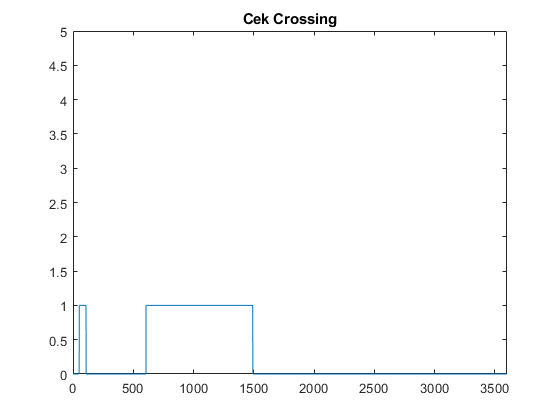


conflict_cross = plot(Cek_crossing);
xlim([0 3600]);
ylim([0 5]);
title('Cek Crossing');

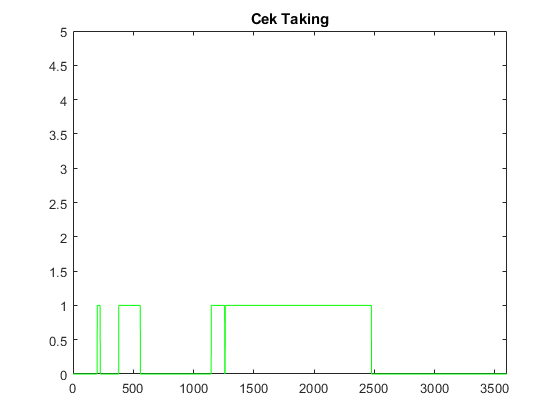


% hold on;
conflict_taking = plot(Cek_taking,'g');
title('Cek Taking')
xlim([0 3600]);
ylim([0 5]);

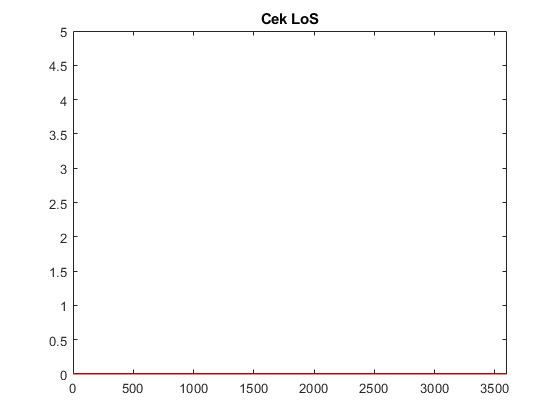


Cek_LoS = plot(Cek_LoS,'r');
title('Cek LoS')
xlim([0 3600]);
ylim([0 5]);

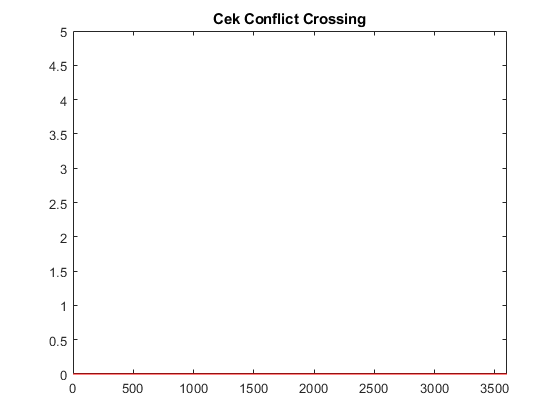


Cek_conflicting_crossing = plot(Cek_conflict_crossing,'r');
title('Cek Conflict Crossing')
xlim([0 3600]);
ylim([0 5]);


% hold off